# Using NWB Data

*last updated: January 1st, 2023*

In this tutorial, we demonstrate the reading and usage of the NWB file produced in the [File Conversion Tutorial](https://matnwb.readthedocs.io/en/latest/pages/tutorials/convertTrials.html). The output is a near-reproduction of Figure 1e from the [Li et al](https://www.ncbi.nlm.nih.gov/pubmed/27074502) publication, showing raster and peristimulus time histogram (PSTH) plots for neural recordings from anterior lateral motor cortex (ALM). This figure illustrates the main finding of the publication, showing the robustness of motor planning behavior and neural dynamics following short unilateral network silencing via optogenetic inhibition. 

## Reading NWB Files

NWB files can be read in using the *nwbRead()* function.  This function returns a *nwbfile* object which is the in-memory representation of the NWB file structure.

nwb = nwbRead('out\ANM255201_20141124.nwb', 'ignorecache');

## **Constrained Sets**

Analyzed data in NWB is placed under the *analysis* property, which is a **Constrained Set**.  A constrained set consists of an arbitrary amount of key-value pairs similar to [Map containers](https://www.mathworks.com/help/matlab/map-containers.html) in MATLAB or a dictionary in Python.  However, constrained sets also have the ability to validate their own properties closer to how a typed Object would.

You can get/set values in constrained sets using their respective *.get()/.set()* methods and retrieve all Set properties using the *keys() *method, like in a *containers.Map.*

unit_names = keys(nwb.analysis);

## Dictionaries with MATLAB R2022b

As noted above, constrained sets uses Map container objects, a custom class that allows user to retrieve values using a corresponding key.  For users working with MATLAB version R2022b, a notable addition of the [dictionary](https://www.mathworks.com/help/matlab/ref/dictionary.html?s_tid=doc_ta) object offers significantly faster functionality.

You can initialize a dictionary and configure its contents from relevant analysed NWB data with the same key/values noted above. 

Number of entries in a dictionary can be done with the new [numEntries()](https://www.mathworks.com/help/matlab/ref/dictionary.numentries.html) function. One can also return all the keys and values of a dictionary as arrays using [keys(dict_name)](https://www.mathworks.com/help/matlab/ref/dictionary.keys.html) and [values(dict_name)](https://www.mathworks.com/help/matlab/ref/dictionary.values.html) functions. 

## Dynamic Tables

*nwb.intervals_trials* returns a unique type of table called a **Dynamic Table**.  Dynamic tables inherit from the NWB type *types.hdmf_common.DynamicTable* and allow for a table-like interface in NWB.  In the case below, we grab the special column *start_time*.  Dynamic Tables allow adding your own vectors using the *vectordata* property, which are Constrained Sets.  All columns are represented by either a *types.hdmf_common.VectorData *or a *types.hdmf_common.VectorIndex* type.

## Data Stubs

The *data* property of the column *id* in *nwb.units* is a *types.untyped.DataStub.*  This object is a representation of a dataset that is not loaded in memory, and is what allows MatNWB to lazily load its file data.  To load the data into memory, use the *.load() *method which extracts all data from the NWB file. Alternatively, you can index into the DataStub directly using conventional MATLAB syntax.

## Jagged Arrays in Dynamic Tables

With the new addition of *addRow* and *getRow* to Dynamic Tables, the concept of jagged arrays can be worked around and no longer require full understanding outside of specific data format concerns or low-level nwb tool development. The below paragraph is retained in its entirety from its original form as purely informational.

All data in a Dynamic Table must be aligned by row and column, but not all data fits into this paradigm neatly.  In order to represent variable amounts of data that is localised to each row and column, NWB uses a concept called **Jagged Arrays**.  These arrays consist of two column types: the familiar *types.core.VectorData*, and the new *types.core.VectorIndex*.  A Vector Index holds no data, instead holding a reference to another Vector Data and a vector of indices that align to the Dynamic Table dimensions.  The indices represent the last index boundary in the Vector Data object for the Vector Index row.  As an example, an index of three in the first row of the Vector Index column points to the first three values in the referenced Vector Data column.  Subsequently, if the next index were a five, it would indicate the fourth and fifth elements in the referenced Vector Data column.

The jagged arrays serve to represent multiple trials and spike times associated to each unit by id. A convenient way to represent these in MATLAB is to use [Map containers](https://www.mathworks.com/help/matlab/map-containers.html) where each unit's data is indexed directly by its unit id. Below, we utilize *getRow* in order to build the same Map.

Once again, for users with MATLAB R2022b versions or newer, we can utilize MATLAB  [dictionary](https://www.mathworks.com/help/matlab/ref/dictionary.html?s_tid=doc_ta) objects instead of map containers to build the Map. 

unit_ids = nwb.units.id.data.load(); % array of unit ids represented within this

% Initialize trials & times Map containers indexed by unit_ids
unit_trials = containers.Map('KeyType',class(unit_ids),'ValueType','any');
unit_times = containers.Map('KeyType',class(unit_ids),'ValueType','any');

#### MATLAB R2022b Versions

% unit_trials = dictionary();
% unit_times  = dictionary();

Adding key-value pairs, one at a time:

last_idx = 0;
for i = 1:length(unit_ids)
    unit_id = unit_ids(i);
    
    row = nwb.units.getRow(unit_id, 'useId', true, 'columns', {'spike_times', 'trials'});
    unit_trials(unit_id) = row.trials{1};
    unit_times(unit_id) = row.spike_times{1};
end

## Process Units

We now do the following for each Unit:

- Filter out invalid trials

- Separate datasets based on resulting mouse behavior (right/left licks).

- Derive "sample", "delay", and "response" times for this analyzed neuron.

- Compose a peristimulus time histogram from the data.


sorted_ids = sort(unit_ids);
Photostim = struct(...
    'ind', true,... % mask into xs and ys for this photostim
    'period', 'none',...
    'duration', 0,... % in seconds
    'ramp_offset', 0); % in seconds

% Initialize Map container of plotting data for each unit, stored as structure
Unit = containers.Map('KeyType',class(unit_ids),'ValueType','any');

#### MATLAB R2022b Versions

% Unit = dictionary();

Initializing unit structure:

unit_struct = struct(...
    'id', [],...
    'xs', [],...
    'ys', [],...
    'xlim', [-Inf Inf],...
    'sample', 0,...
    'delay', 0,...
    'response', 0,...
    'left_scatter', false,...
    'right_scatter', false,...
    'photostim', Photostim); % can have multiple photostim

for unit_id = unit_ids'

We first extract trial IDs from the Unit IDs.

    unit_trial_id = unit_trials(unit_id);

Then filter out outliers from the Sample, Delay, and Response time points with which we derive a "good enough" estimate.

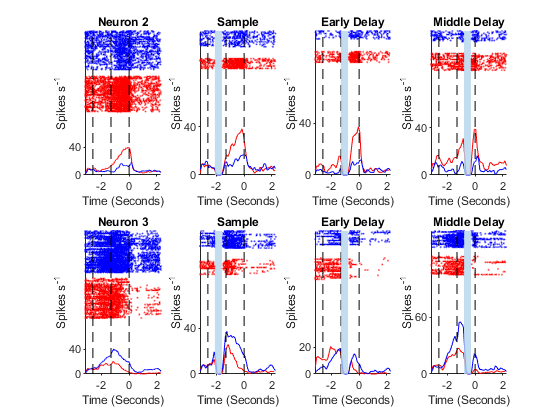

    trial = nwb.intervals_trials.getRow(unit_trial_id, 'useId', true,...
        'columns', {'PoleInTime', 'PoleOutTime', 'CueTime', 'GoodTrials'});
    unit_sample = trial.PoleInTime;
    unit_delay = trial.PoleOutTime;
    unit_response = trial.CueTime;
    unit_good_trials = trial.GoodTrials;
    
    % Subjective parameters
    delay_threshold = 0.064;
    response_threshold = 0.43;
    expected_delay_offset = 1.3; % determined from figure 1a
    expected_response_offset = 1.3;
    
    expected_delay = unit_sample + expected_delay_offset;
    expected_response = unit_delay + expected_response_offset;
    good_delay = (unit_delay > expected_delay - delay_threshold) &...
        (unit_delay < expected_delay + delay_threshold);
    good_response = (unit_response > expected_response - response_threshold) &...
        (unit_response < expected_response + response_threshold);
    avg_sample = mean(unit_sample(good_delay & good_response));
    avg_delay = mean(unit_delay(good_delay & good_response));
    avg_response = mean(unit_response(good_delay & good_response));

Filter the rest of the data by "good" trials.

    unit_good_trials = unit_good_trials & good_delay & good_response;
    
    unit_trial_id = unit_trial_id(unit_good_trials);
    
    unit_spike_time = unit_times(unit_id);
    unit_spike_time = unit_spike_time(unit_good_trials);

Retrieve good trial data and organize by stimulation type.

    trial = nwb.intervals_trials.getRow(unit_trial_id, 'useId', true,...
        'columns', {'start_time', 'HitR', 'HitL', 'StimTrials', 'PhotostimulationType'});
    unit_is_photostim = logical(trial.StimTrials);
    unit_stim_type = trial.PhotostimulationType;
    
    unit_no_stim = ~unit_is_photostim & 0 == unit_stim_type;
    unit_sample_stim = unit_is_photostim & 1 == unit_stim_type;
    unit_early_stim = unit_is_photostim & 2 == unit_stim_type;
    unit_middle_stim = unit_is_photostim & 3 == unit_stim_type;

Compose Scatter Plots and the Peristimulus Time Histogram zeroed on the Response time.

    xs = unit_spike_time - trial.start_time - avg_response;
    ys = unit_trial_id;
    
    curr_unit = unit_struct;
    
    curr_unit.xs = xs;
    curr_unit.ys = ys;
    curr_unit.left_scatter = logical(trial.HitL);
    curr_unit.right_scatter = logical(trial.HitR);
    curr_unit.sample = avg_sample - avg_response;
    curr_unit.delay = avg_delay - avg_response;
    curr_unit.response = 0;
    
    % Photostim periods
    curr_unit.photostim.ind = unit_no_stim;
    
    % Sample
    if any(unit_sample_stim)
        SampleStim = Photostim;
        SampleStim.ind = unit_sample_stim;
        SampleStim.period = 'Sample';
        SampleStim.duration = 0.5;
        SampleStim.ramp_offset = 0.1;
        curr_unit.photostim(end+1) = SampleStim;
    end
    
    % Early Delay
    if any(unit_early_stim)
        early_stim_types = unique(unit_stim_type(unit_early_stim));
        for i_early_types=1:length(early_stim_types)
            early_type = early_stim_types(i_early_types);
            EarlyStim = Photostim;
            EarlyStim.period = 'Early Delay';
            EarlyStim.ind = early_type == unit_stim_type & unit_early_stim;
            if early_type == 2
                EarlyStim.duration = 0.5;
                EarlyStim.ramp_offset = 0.1;
            else
                EarlyStim.duration = 0.8;
                EarlyStim.ramp_offset = 0.2;
            end
            curr_unit.photostim(end+1) = EarlyStim;
        end
    end
    
    % Middle Delay
    if any(unit_middle_stim)
        MiddleStim = Photostim;
        MiddleStim.ind = unit_middle_stim;
        MiddleStim.period = 'Middle Delay';
        MiddleStim.duration = 0.5;
        MiddleStim.ramp_offset = 0.1;
        curr_unit.photostim(end+1) = MiddleStim;
    end
    
    Unit(unit_id) = curr_unit;
end

## Plot Example Neurons

neuron_labels = [2, 3]; % neuron labels from Figure 1e
neuron_ids = [11, 2]; % neuron unit IDs corresponding to the Fig 1e labels
num_conditions = 4; % photostim conditions: nostim, sample, early, middle if applicable
num_neurons = length(neuron_ids);

% Initialize data structures for each summary plot of categorized neural spike data at specified stimulus condition
RasterPlot = struct(...
    'xs', 0,...
    'ys', 0);
ConditionPlot = struct(...
    'label', '',...
    'xlim', 0,...
    'sample', 0,...
    'delay', 0,...
    'response', 0,...
    'right_scatter', RasterPlot,...
    'left_scatter', RasterPlot,...
    'psth_bin_window', 0,...
    'stim_type', '');
fig = figure;

% Plot neural spike data for each neuron and stimulus condition in a subplot array: num_neurons (rows) x num_conditions (columns)
for nn=1:num_neurons
    
    Neuron = Unit(neuron_ids(nn));
    
    % Initialize structure with neural + stimulus condition data
    CurrPlot = ConditionPlot;
    CurrPlot.xlim = [min(Neuron.xs) max(Neuron.xs)];
    CurrPlot.sample = Neuron.sample;
    CurrPlot.delay = Neuron.delay;
    CurrPlot.response = Neuron.response;
    
    % Plot each neuron/condition
    plot_row = (nn - 1) * num_conditions;
    for cc=1:num_conditions
        ax = subplot(num_neurons, num_conditions, plot_row + cc, 'Parent', fig);
        Stim = Neuron.photostim(cc);
        
        CurrPlot.stim_type = Stim.period;
        if strcmp(Stim.period, 'none')
            CurrPlot.label = sprintf('Neuron %d', neuron_labels(nn));
            CurrPlot.psth_bin_window = 9;
        else
            CurrPlot.label = Stim.period;
            CurrPlot.psth_bin_window = 2;
        end
        
        stim_left_scatter_ind = Stim.ind & Neuron.left_scatter;
        stim_left_scatter_trials = Neuron.ys(stim_left_scatter_ind);
        
        CurrPlot.left_scatter.xs = Neuron.xs(stim_left_scatter_ind);
        [~,CurrPlot.left_scatter.ys] = ismember(stim_left_scatter_trials,unique(stim_left_scatter_trials));
        
        stim_right_scatter_ind = Stim.ind & Neuron.right_scatter;
        stim_right_scatter_trials = Neuron.ys(stim_right_scatter_ind);
        
        CurrPlot.right_scatter.xs = Neuron.xs(stim_right_scatter_ind);
        [~,CurrPlot.right_scatter.ys] = ismember(stim_right_scatter_trials,unique(stim_right_scatter_trials));
        
        plot_condition(ax, CurrPlot);
    end
end

## Helper Functions

PSTH helper function

function [psth_xs, psth_ys] = calculate_psth(xs, bin_window, bin_width)
[bin_counts, edges]  = histcounts(xs, 'BinWidth', bin_width);
psth_xs = edges(1:end-1) + (bin_width / 2);

moving_avg_b = (1/bin_window) * ones(1,bin_window);
psth_ys = filter(moving_avg_b, 1, bin_counts);
end

Plotter function for each stimulus condition

function plot_condition(ax, ConditionPlot)
left_cdata = [1 0 0]; % red
right_cdata = [0 0 1]; % blue
hist_margin = 50;
scatter_margin = 10;

% Calculate PSTH values
% moving average over 200 ms as per figure 1e
hist_bin_width = 0.2 / ConditionPlot.psth_bin_window;
[left_psth_xs, left_psth_ys] =...
    calculate_psth(ConditionPlot.left_scatter.xs, ConditionPlot.psth_bin_window, hist_bin_width);
[right_psth_xs, right_psth_ys] =...
    calculate_psth(ConditionPlot.right_scatter.xs, ConditionPlot.psth_bin_window, hist_bin_width);

right_scatter_offset = min(ConditionPlot.right_scatter.ys);
right_scatter_height = max(ConditionPlot.right_scatter.ys) - right_scatter_offset;
left_scatter_offset = min(ConditionPlot.left_scatter.ys);
left_scatter_height = max(ConditionPlot.left_scatter.ys) - left_scatter_offset;
psth_height = max([left_psth_ys right_psth_ys]);

left_y_offset = hist_margin...
    + psth_height...
    - left_scatter_offset;

right_y_offset = scatter_margin...
    + left_y_offset...
    + left_scatter_offset...
    + left_scatter_height...
    - right_scatter_offset;

subplot_height = right_y_offset...
    + right_scatter_offset...
    + right_scatter_height;

hold(ax, 'on');

% PSTH
plot(ax, left_psth_xs, left_psth_ys, 'Color', left_cdata);
plot(ax, right_psth_xs, right_psth_ys, 'Color', right_cdata);

% Scatter Plot
scatter(ax,...
    ConditionPlot.left_scatter.xs,...
    left_y_offset + ConditionPlot.left_scatter.ys,...
    'Marker', '.',...
    'CData', left_cdata,...
    'SizeData', 1);
scatter(ax,...
    ConditionPlot.right_scatter.xs,...
    right_y_offset + ConditionPlot.right_scatter.ys,...
    'Marker', '.',...
    'CData', right_cdata,...
    'SizeData', 1);

% sample, delay, response lines
line(ax, repmat(ConditionPlot.sample, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');
line(ax, repmat(ConditionPlot.delay, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');
line(ax, repmat(ConditionPlot.response, 1, 2), [0 subplot_height],...
    'Color', 'k', 'LineStyle', '--');

% blue bar for photoinhibition period
if ~strcmp(ConditionPlot.stim_type, 'none')
    stim_height = subplot_height;
    stim_width = 0.5; % seconds
    % end time relative to 'go' cue as described in the paper.
    switch ConditionPlot.stim_type
        case 'Sample'
            end_offset = 1.6;
        case 'Early Delay'
            end_offset = 0.8;
        case 'Middle Delay'
            end_offset = 0.3;
        otherwise
            error('Invalid photostim period `%s`', ConditionPlot.stim_type);
    end
    stim_offset = ConditionPlot.response - stim_width - end_offset;
    patch_vertices = [...
        stim_offset, 0;...
        stim_offset, stim_height;...
        stim_offset+stim_width, stim_height;...
        stim_offset+stim_width, 0];
    patch(ax,...
        'Faces', 1:4,...
        'Vertices', patch_vertices,...
        'FaceColor', '#B3D3EC',...  % light blue shading
        'EdgeColor', 'none',...
        'FaceAlpha', 0.8);
end

title(ax, ConditionPlot.label);
xlabel(ax, 'Time (Seconds)');
ylabel(ax, 'Spikes s^{-1}')
xticks(ax, [-2 0 2]);
yticks(ax, [0 max(10, round(psth_height, -1))]);
%     legend(ax, [scatter_left_plot, scatter_right_plot], {'Left Lick', 'Right Lick'},...
%         'location', 'northwestoutside');
ax.TickDir = 'out';
ax.XLim = ConditionPlot.xlim;
ax.YLim = [0 subplot_height];

hold(ax, 'off');
end